syms W L V_y V_x d x_0 t theta_pan theta_dot_pan 
theta_pan_sym = atan( (V_x * t - 1/2 * L) / (d + 1/2 * W) )

$$theta\_pan\_sym = -\mathrm{atan}\left(\frac{\frac{L}{2}-V_{x}\,t}{\frac{W}{2}+d}\right)$$

theta_dot_pan_sym = diff(theta_pan_sym)

$$theta\_dot\_pan\_sym = \frac{V_{x}}{\left(\frac{{\left(\frac{L}{2}-V_{x}\,t\right)}^{2}}{{\left(\frac{W}{2}+d\right)}^{2}}+1\right)\,\left(\frac{W}{2}+d\right)}$$

t_max_sym = L/V_x

$$t\_max\_sym = \frac{L}{V_{x}}$$

s      = [W  L  V_y V_x d t theta_pan theta_dot_pan];
s_real = [20 40 0   39  2 t theta_pan theta_dot_pan];

theta_pan_real = subs(theta_pan_sym, s, s_real)

$$theta\_pan\_real = \mathrm{atan}\left(\frac{13\,t}{4}-\frac{5}{3}\right)$$

theta_dot_pan_real = subs(theta_dot_pan_sym, s, s_real)

$$theta\_dot\_pan\_real = \frac{13}{4\,\left(\frac{{\left(39\,t-20\right)}^{2}}{144}+1\right)}$$

t_max = double(subs(t_max_sym, s, s_real))

t_max = 1.0256


theta_dot_pan = @(time) subs(theta_dot_pan_real, t, time)

theta_dot_pan = function_handle with value:
    @(time)subs(theta_dot_pan_real,t,time)


t = 0:0.01:t_max

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


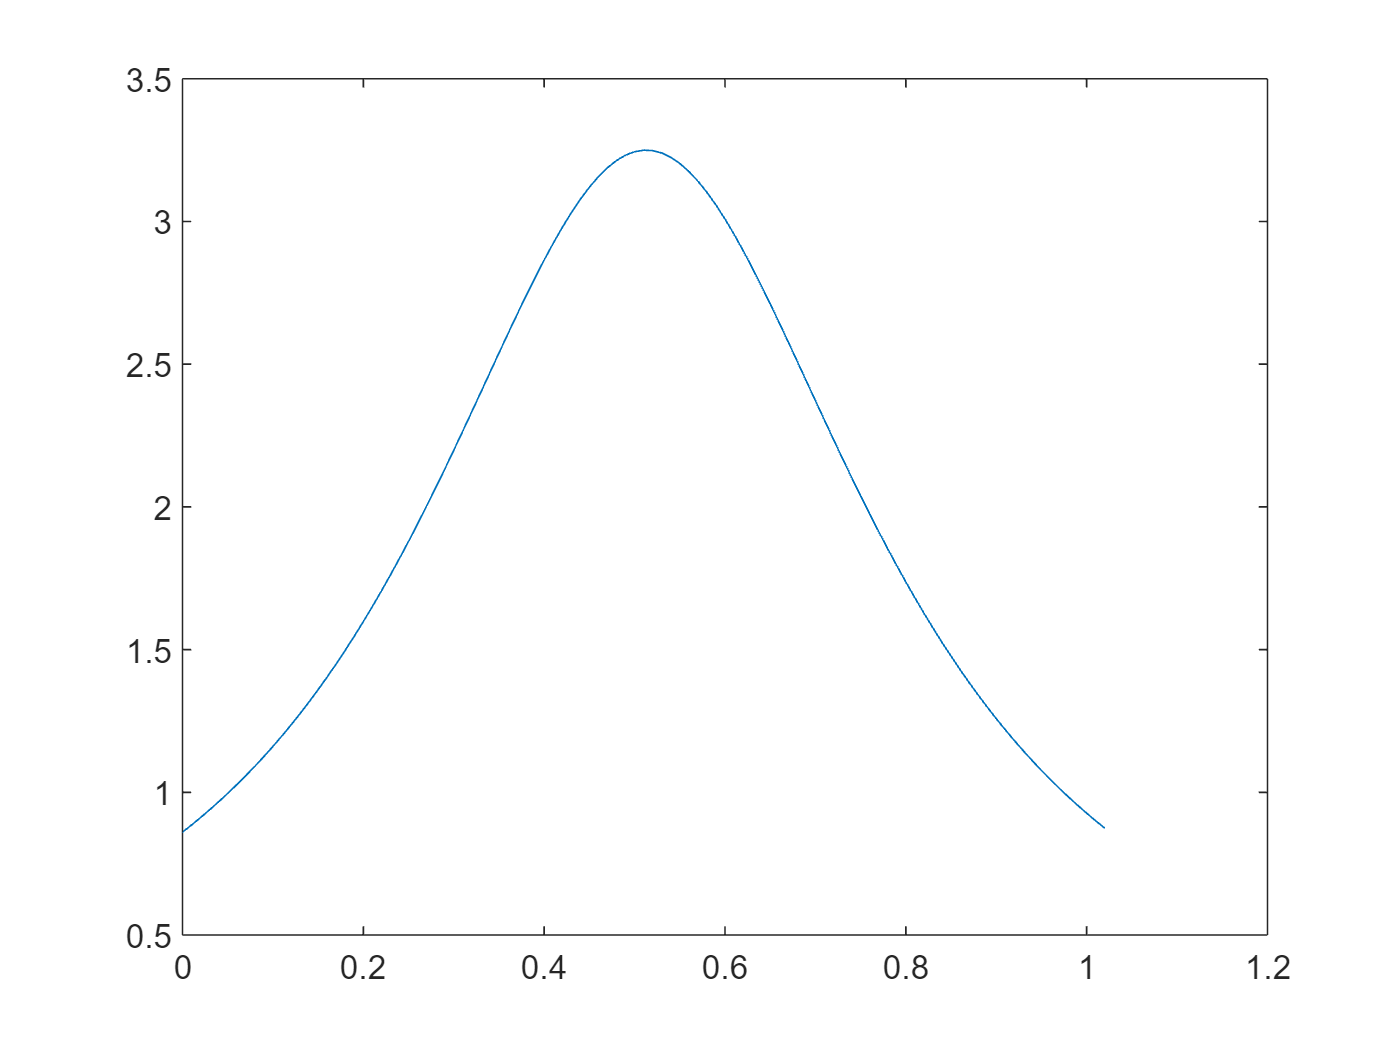

plot(t, theta_dot_pan(t))